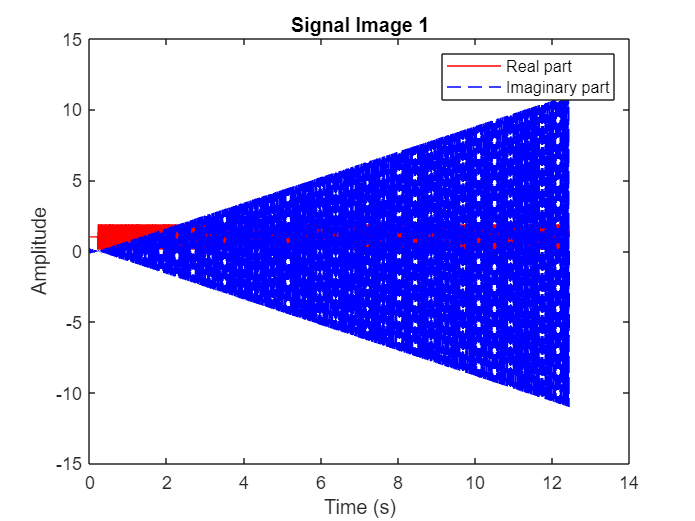

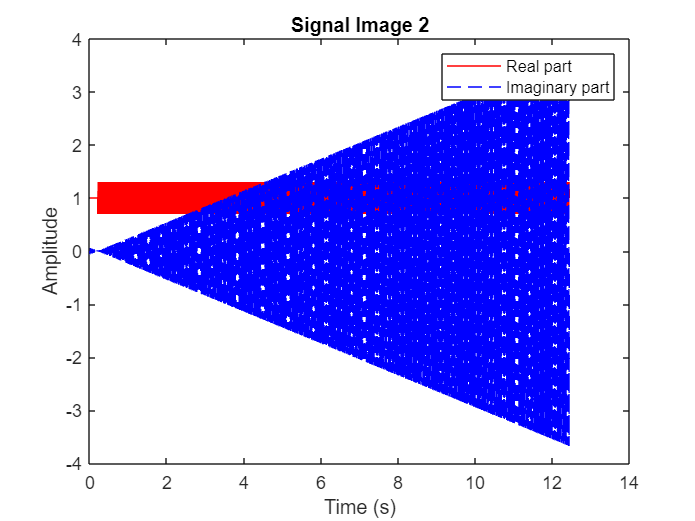

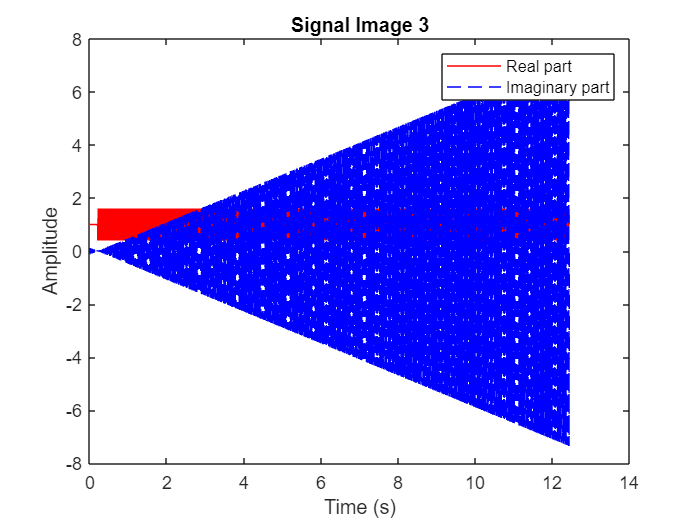

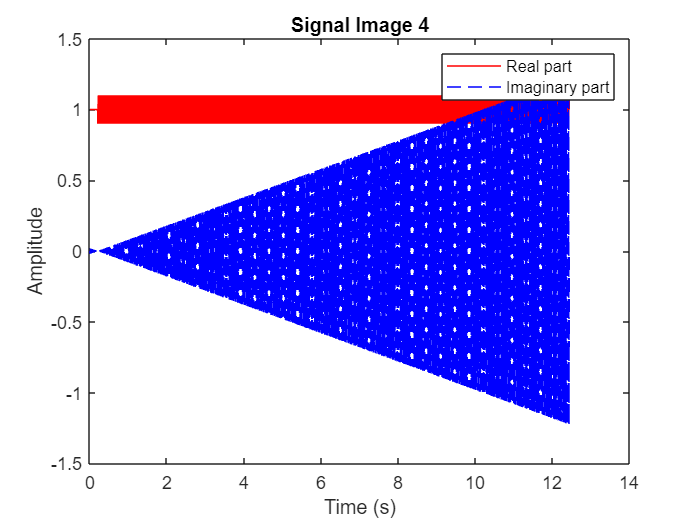

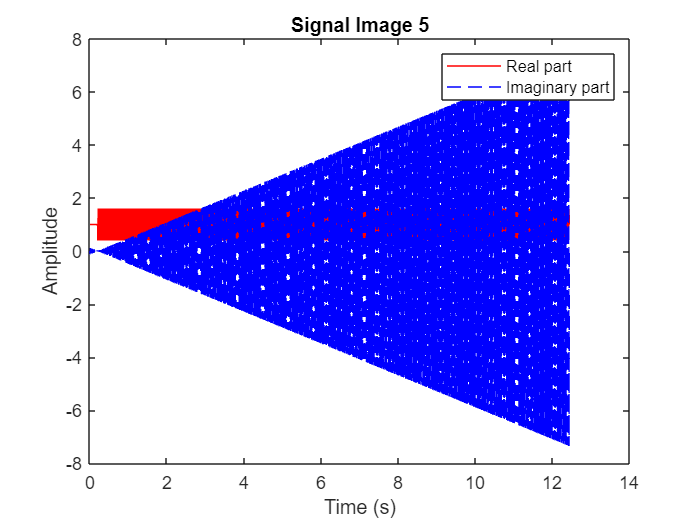

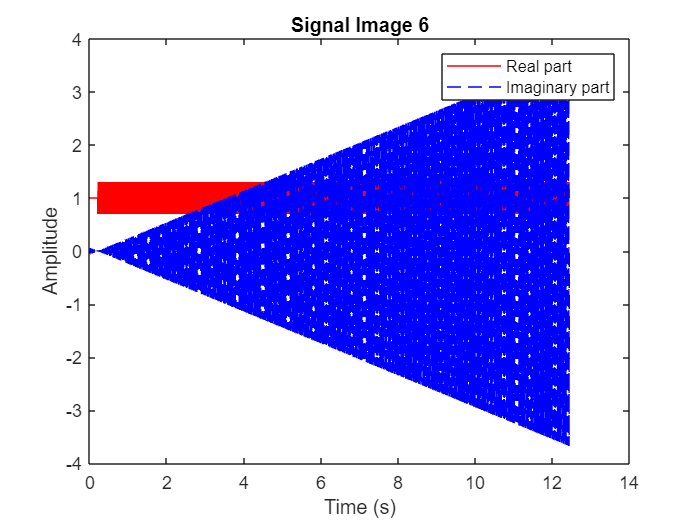

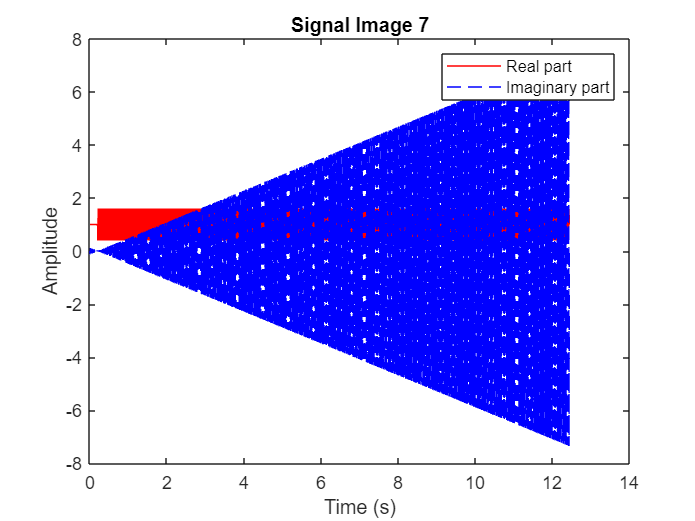

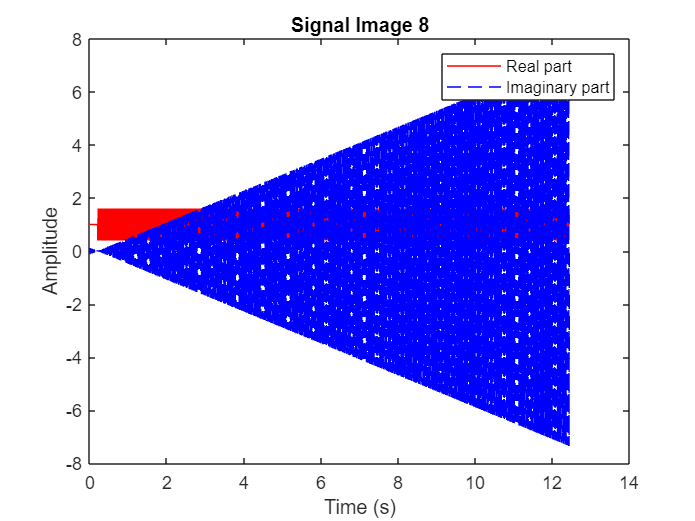

% Parameters
A = 1;                   % Amplitude
f = 50;                  % Frequency in Hz
sampling_rate = 3200;    % Sampling rate in Hz
num_cycles = 622;        % Number of cycles considered

% Time vector
T = 1 / f;                                      % Period of one cycle
duration = num_cycles * T;                      % Total duration of the signal
num_samples = duration * sampling_rate + 1;     % Number of samples
t = linspace(0, duration, num_samples);         % Time vector

% Angular frequency of the sinusoidal signal
omega = 2 * pi * f;
num_signals = 50;
u = @(t) ones(size(t)) .* (t >= 0);


% Generate 50 images of signals
for signal_index = 1:num_signals
    % Define parameter m
    m_values = [0.1, 0.3, 0.6, 0.9];            % Values of m
    m_index = randi(length(m_values));          % Randomly select m from the list
    m = m_values(m_index);
    
    % Define t1 and t2 (you can choose appropriate values)
    t1 = 0.5;  % Placeholder for t1 value, you can assign a value accordingly
    t2 = 0.2;  % Placeholder for t2 value, you can assign a value accordingly
    
    % Calculate the signal
    signal = (1 - m * (u(t - t2) - 1j * (t - t2)) .* (sin(omega * t)));
    
    % Plot the signal
    figure;
    plot(t, real(signal), 'r-', t, imag(signal), 'b--');
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Signal Image ', num2str(signal_index)]);
    legend('Real part', 'Imaginary part');
end